# EPL 2015-2016 Season Data

## Intro

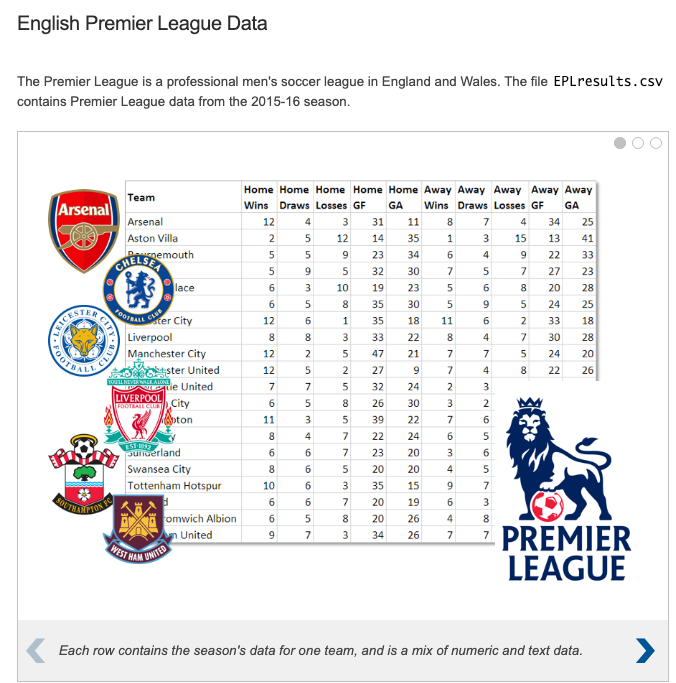

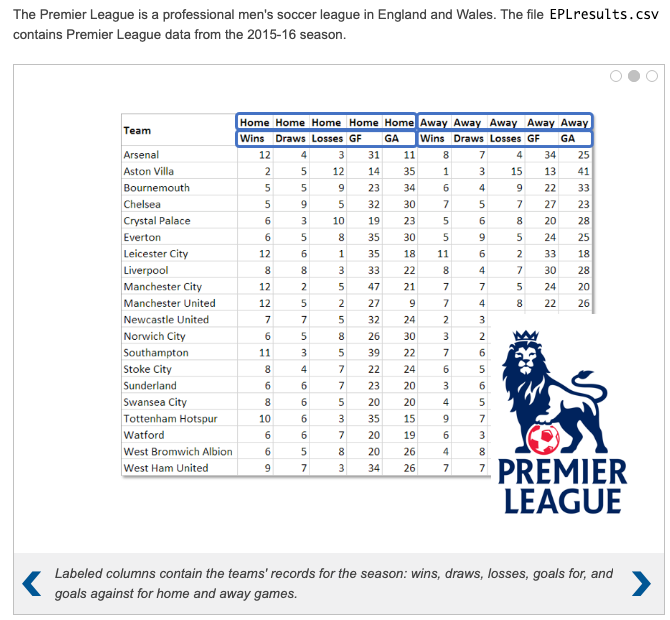

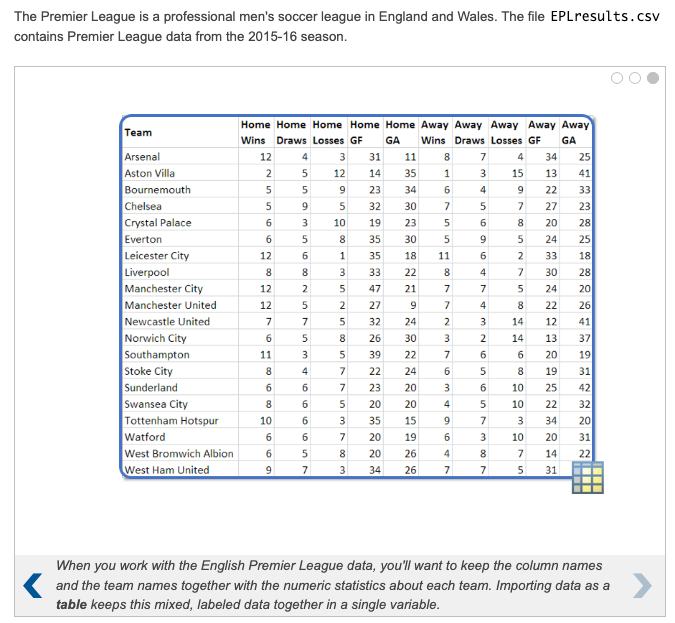

## Import data

讀檔可以用 code 讀，也可以用 GUI: `Home/Import Data/...`

EPL = readtable('EPLresults.csv');

teamInfo = readtable('EPLteams.csv');

可以看一下 summary

summary(EPL)

Variables:

    Team: 20×1 cell array of character vectors

        Properties:
            Description:  Team
    HomeWins: 20×1 double

        Properties:
            Description:  Home Wins
        Values:

            Min           2   
            Median      7.5   
            Max          12   

    HomeDraws: 20×1 double

        Properties:
            Description:  Home Draws
        Values:

            Min          2    
            Median       5    
            Max          9    

    HomeLosses: 20×1 double

        Properties:
            Description:  Home Losses
        Values:

            Min           1   
            Median        5   
            Max          12   

    HomeGF: 20×1 double

        Properties:
            Description:  Home GF
        Values:

            Min          14   
            Median       29   
            Max          47   

    HomeGA

## Final Standings

Calculate points and goal differential.

EPL.Points = 3*(EPL.HomeWins + EPL.AwayWins) + EPL.HomeDraws + EPL.AwayDraws;
EPL.GoalDifference = EPL.HomeGF + EPL.AwayGF - EPL.HomeGA - EPL.AwayGA;
EPL = movevars(EPL,{'Points','GoalDifference'},'After','Team');

Sort teams by highest points, then highest goal differential.

EPL = sortrows(EPL,{'Points','GoalDifference'},'descend')

EPL = 20×13 table
             Team             Points    GoalDifference    HomeWins    HomeDraws    HomeLosses    HomeGF    HomeGA    AwayWins    AwayDraws    AwayLosses    AwayGF    AwayGA
    ______________________    ______    ______________    ________    _________    __________    ______    ______    ________    _________    __________    ______    ______

    'Leicester City'            81            32             12           6             1          35        18         11           6             2          33        18  
    'Arsenal'       

## Effect of Manager Tenure

Combine final standings with `teamInfo`.

EPL = join(EPL(:,1:3),teamInfo);

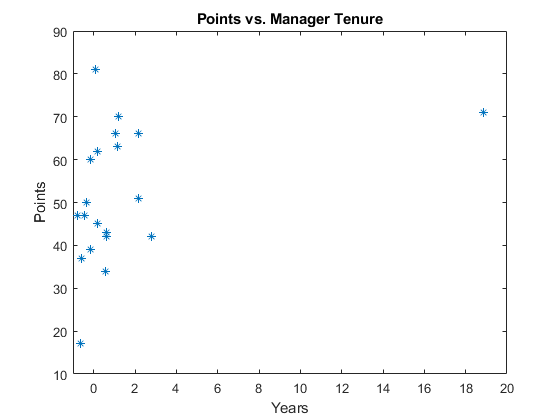

seasonStart = datetime(2015,8,8);
mgTen = seasonStart - EPL.ManagerHireDate;
mgTen = years(mgTen);
plot(mgTen,EPL.Points,'*')
xlim([-1 20])
title('Points vs. Manager Tenure')
ylabel('Points')
xlabel('Years')

Plot over smaller range to ignore outlier (Arsene Wenger).

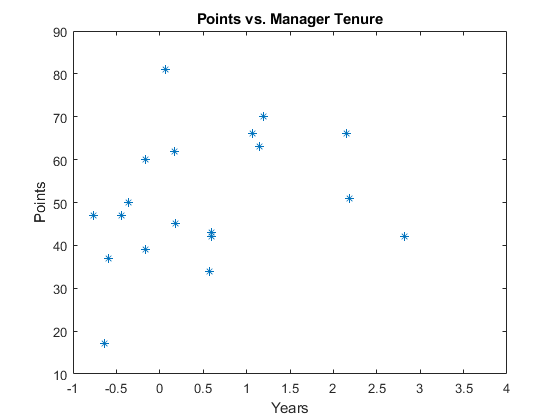

xlim([-1 4])